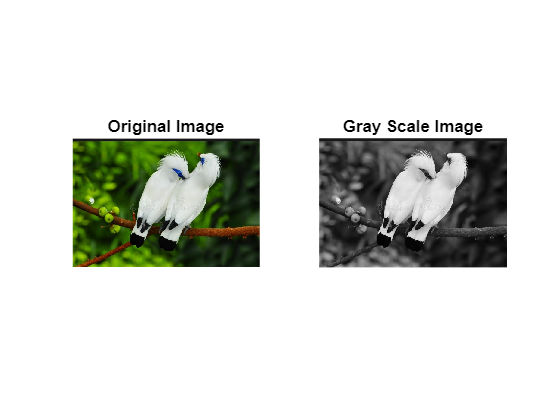

close all
clear
%% Read Image and Calc the Size along with Channels
input_img = imread('bird.jpg');
[x, y, z] = size(input_img); % for RGB z = 3

%% Step - 1 (Conversion of Coloured Image to GrayScale Image
RedChannel = input_img(:, :, 1);
GreenChannel = input_img(:, :, 2);
BlueChannel = input_img(:, :, 3);
% The weights for Channels have been taken from MATLAB rgb2gray HELP File
Gray_Image = .299*double(RedChannel) + .587*double(GreenChannel) + .144*double(BlueChannel);
Gray_Image = uint8(Gray_Image);
% Display the Results
subplot(1,2,1), imshow(input_img), title('Original Image');
subplot(1,2,2), imshow(Gray_Image), title('Gray Scale Image');

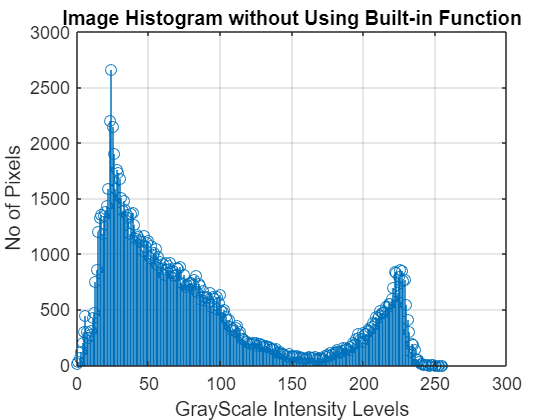


%% Step - 2 (Histogram Plotting without Using the Inbuilt Matlab Command)
img_hist = zeros(1,256);
for i = 1:x % Rows of Input Image
    for j = 1:y % Colms  of input image
        img_hist(Gray_Image(i,j,1)+1) = img_hist(Gray_Image(i,j,1)+1)+1; %Bin Increment for occurrence
    end
end
figure %Plotting the Histogram
stem(0:255, img_hist)
grid on;
ylabel('No of Pixels');
xlabel('GrayScale Intensity Levels'); 
title('Image Histogram without Using Built-in Function');

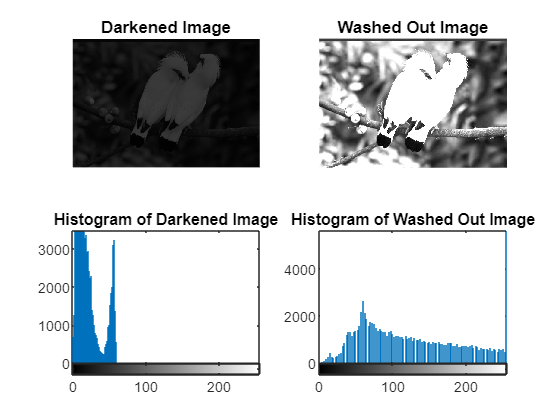


%% Step-3 (Contrast Compression/Degradation)
Darkened_Image = 0.25*Gray_Image; %Image Linear Transformation Scaling(Darkened Image)
Washedout_Image = 2.5*Gray_Image; % Washed Out Image
figure % Plotting the results
subplot(2,2,1), imshow(Darkened_Image), title('Darkened Image');
subplot(2,2,2), imshow(Washedout_Image), title('Washed Out Image');
subplot(2,2,3), imhist(Darkened_Image), title('Histogram of Darkened Image');
subplot(2,2,4), imhist(Washedout_Image), title('Histogram of Washed Out Image');

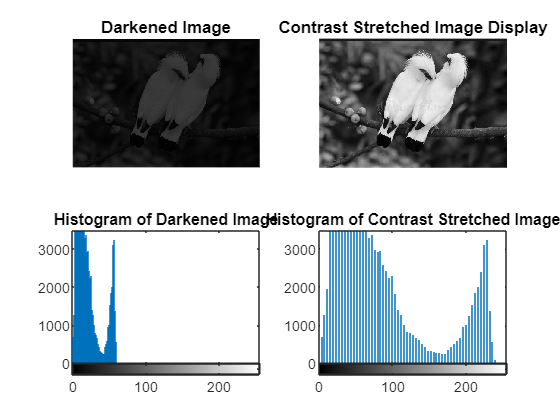

%% Step - 4 (Contrast Stretching/Improvement)
r_min = min(Darkened_Image(:));  % rmin (Min Valued Pixel)
r_max = max(Darkened_Image(:)); % rmax (Max Valued Pixel)
% Image Transformation Using the Contrast Stretching Equation
contrast_stretched_img = (Darkened_Image-r_min).*(255/(r_max-r_min)); 
figure %Plotting the Results in Comparison
subplot(2,2,1), imshow(Darkened_Image), title('Darkened Image');
subplot(2,2,2), imshow(contrast_stretched_img), title('Contrast Stretched Image Display');
subplot(2,2,3), imhist(Darkened_Image), title('Histogram of Darkened Image');
subplot(2,2,4), imhist(contrast_stretched_img), title('Histogram of Contrast Stretched Image');

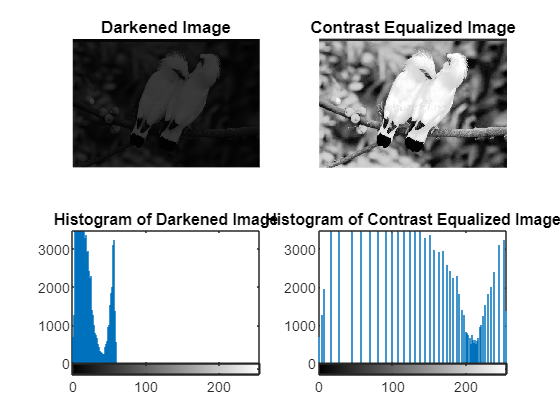

%% Step - 5 (Histogram Equalization)
L = 256; % No of levels
hist = zeros(256,1); % Calc the Histogram 
for i = 1:x % Rows of Input Image
    for j = 1:y % Colms  of input image
        hist(Darkened_Image(i,j,1)+1) = hist(Darkened_Image(i,j,1)+1)+1; %Bin Increment for occurrence
    end
end
norm_hist = hist/numel(Darkened_Image); % PDF (Normalized Histogram
cdf = cumsum(norm_hist); %Using Cumulative Sum function to calc CDF
Hist_Eq = (L-1)*cdf(double(Darkened_Image)+1); %Mapping of Pixel values
Hist_Eq = uint8(Hist_Eq);
figure %Plotting the Results in Comparison
subplot(2,2,1), imshow(Darkened_Image), title('Darkened Image');
subplot(2,2,2), imshow(Hist_Eq), title('Contrast Equalized Image');
subplot(2,2,3), imhist(Darkened_Image), title('Histogram of Darkened Image');
subplot(2,2,4), imhist(Hist_Eq), title('Histogram of Contrast Equalized Image');